clear; close all; clc

% Training set
trainFD001 = readmatrix('train_FD001.txt');
trainFD002 = readmatrix('train_FD002.txt');
trainFD003 = readmatrix('train_FD003.txt');
trainFD004 = readmatrix('train_FD004.txt');

% Test set
testFD001 = readmatrix('test_FD001.txt');
testFD002 = readmatrix('test_FD002.txt');
testFD003 = readmatrix('test_FD003.txt');
testFD004 = readmatrix('test_FD004.txt');

% RUL (Remaining Useful Life)
RUL_FD001 = readmatrix('RUL_FD001.txt');
RUL_FD002 = readmatrix('RUL_FD002.txt');
RUL_FD003 = readmatrix('RUL_FD003.txt');
RUL_FD004 = readmatrix('RUL_FD004.txt');

 Analysis dataset: train_FD001.txt


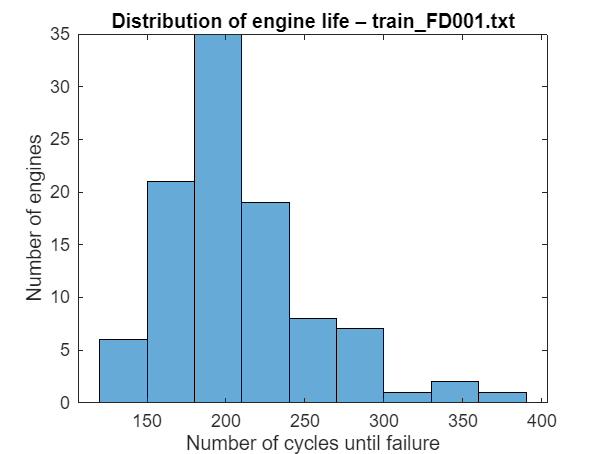

Number of engines: 100


Average engine life (cycles): 206.31


No missing values.


Constant variables:


     3    21    22



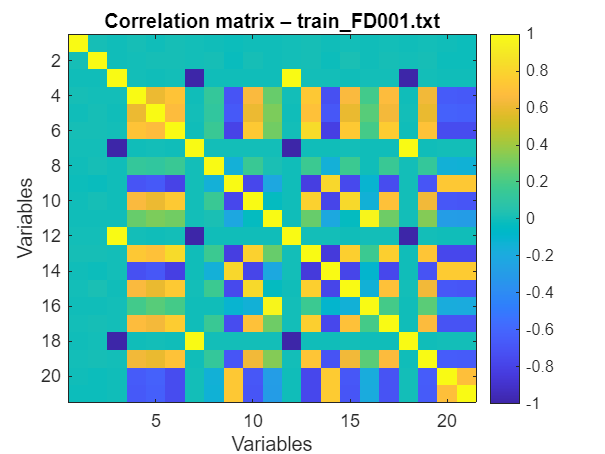

Dataset has 20631 observations (rows) and 21 predictive variables (columns).


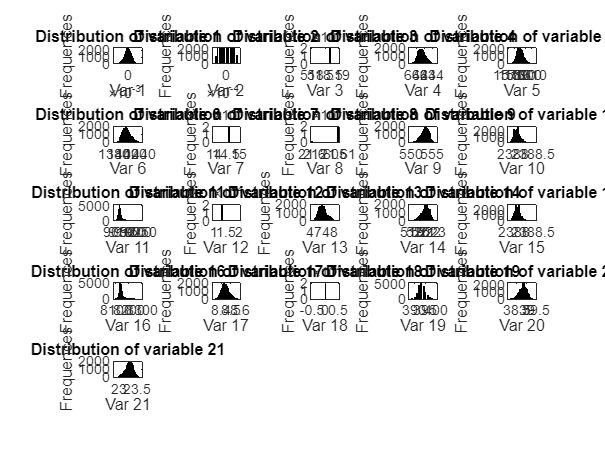

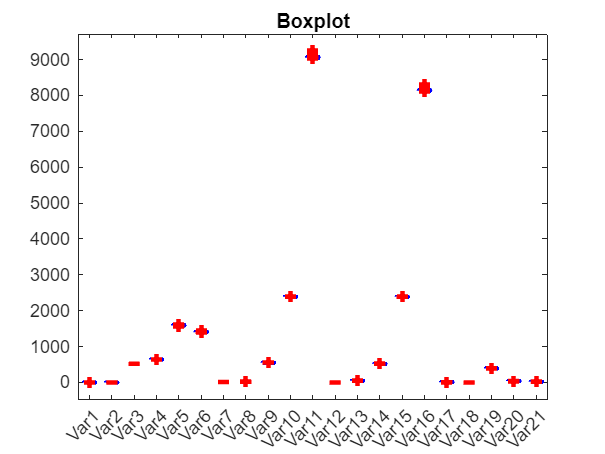

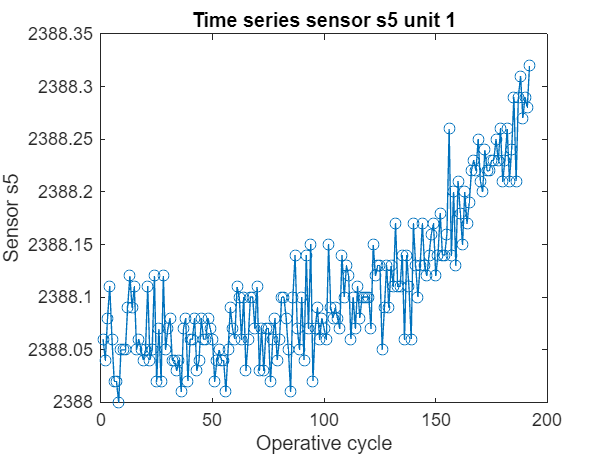

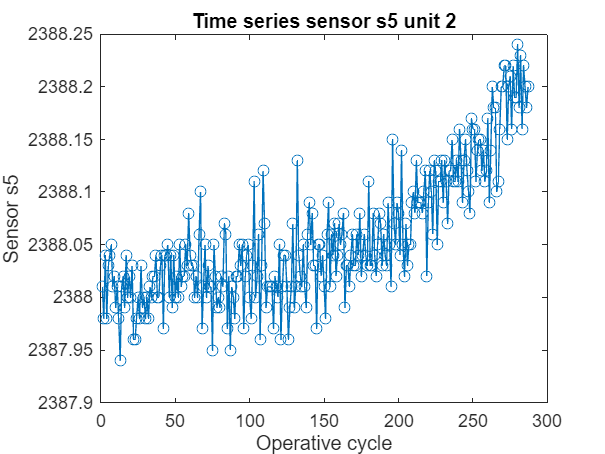

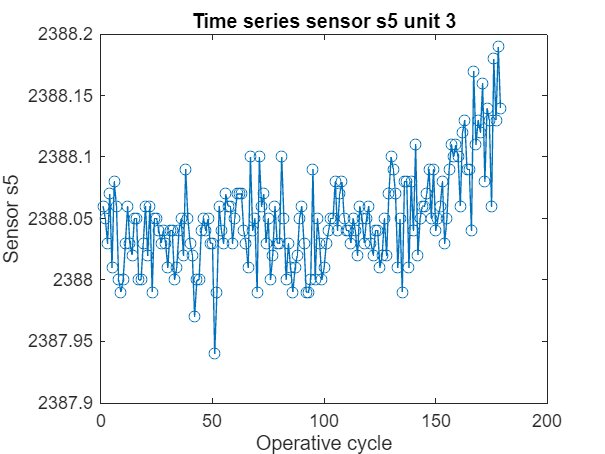


--- PCA Analysis for train_FD001.txt ---


Variance explained by first 10 PCs:


   53.0980   12.3458    5.9549    5.8363    5.6593    2.4338    2.1659    2.0489    1.8002    1.7045



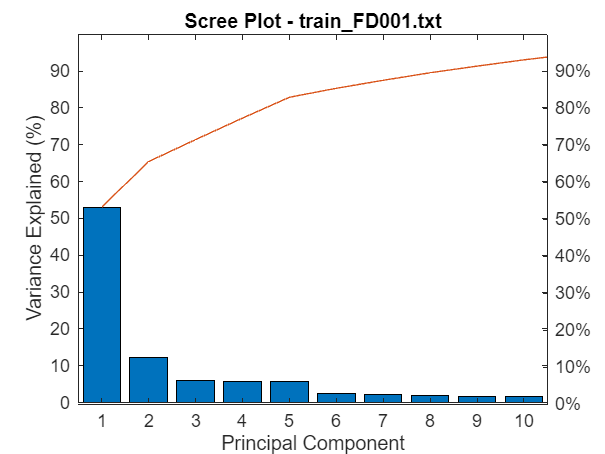

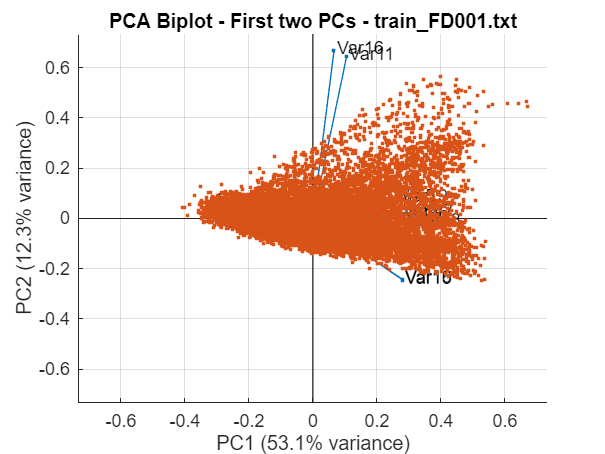

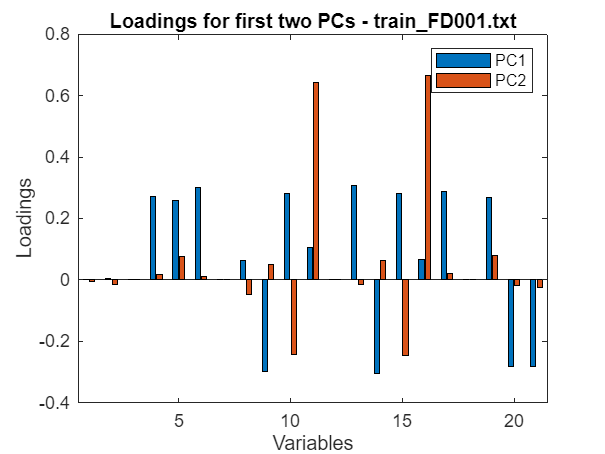


Starting MSPC Modeling for Dataset: train_FD001.txt


No constant variables found.


Dataset has 20631 observations and 21 predictive variables after preprocessing.


 Analysis dataset: train_FD002.txt


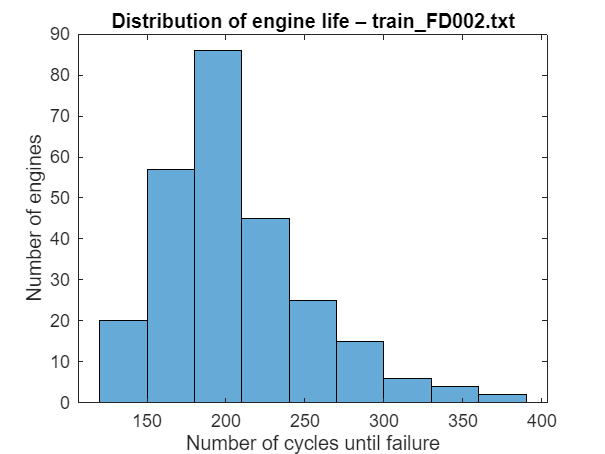

Number of engines: 260


Average engine life (cycles): 206.77


No missing values.


No constant variables.


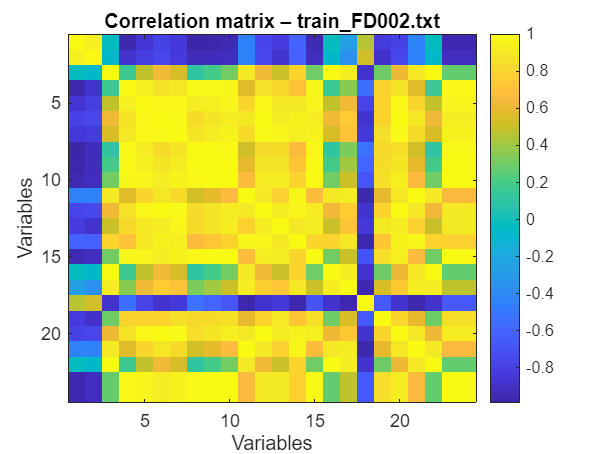

Dataset has 53759 observations (rows) and 24 predictive variables (columns).


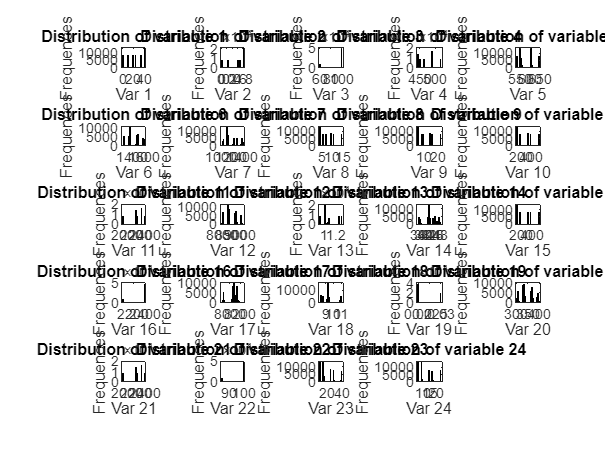

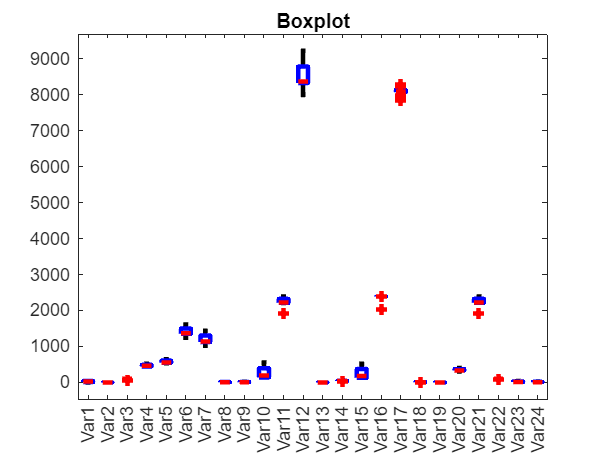

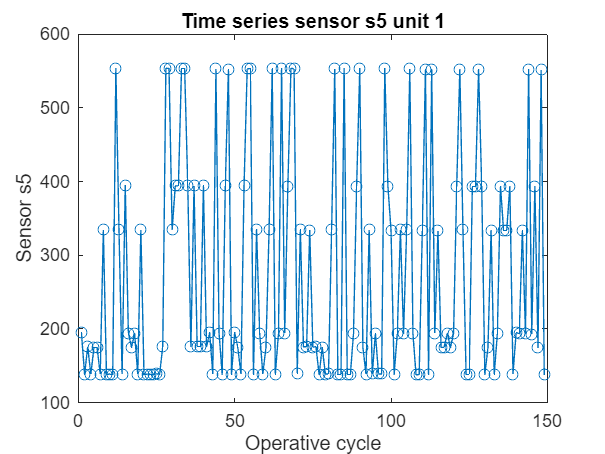

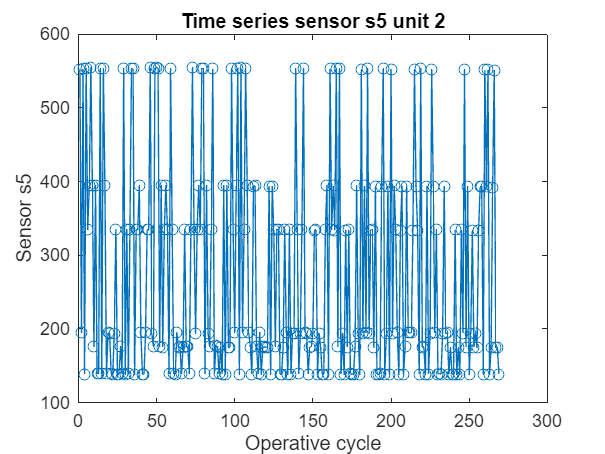

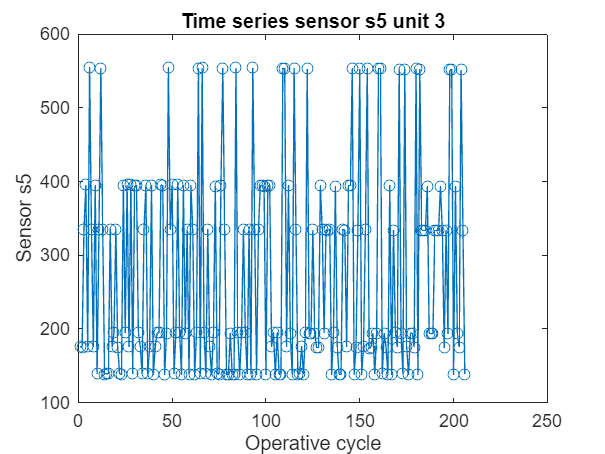


--- PCA Analysis for train_FD002.txt ---


Variance explained by first 10 PCs:


   77.3471   19.9607    1.9075    0.4085    0.1682    0.0960    0.0677    0.0255    0.0056    0.0047



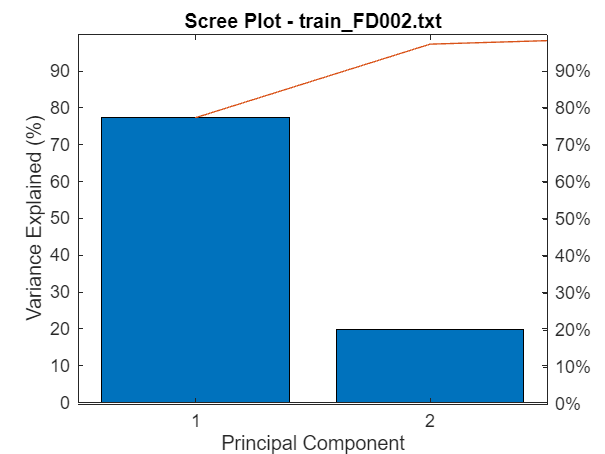

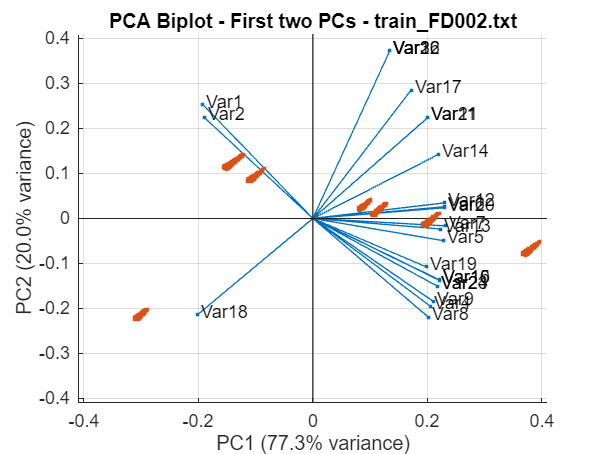

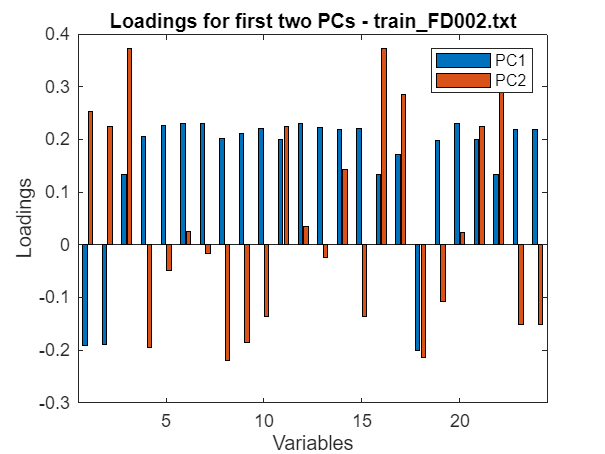


Starting MSPC Modeling for Dataset: train_FD002.txt


No constant variables found.


Dataset has 53759 observations and 24 predictive variables after preprocessing.


 Analysis dataset: train_FD003.txt


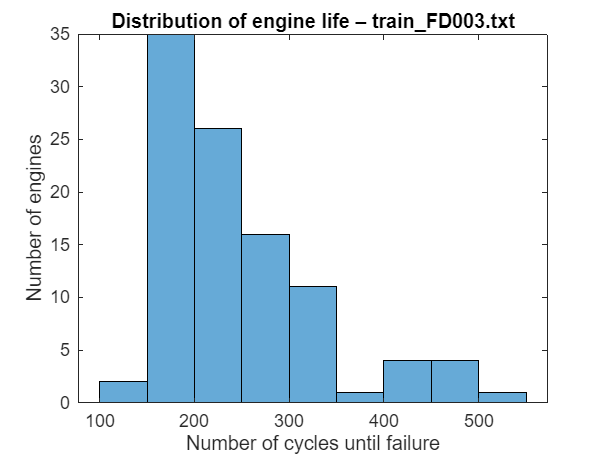

Number of engines: 100


Average engine life (cycles): 247.20


No missing values.


Constant variables:


     3    21    22



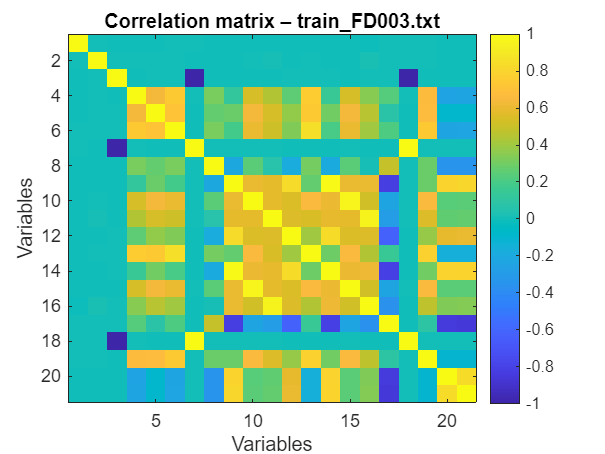

Dataset has 24720 observations (rows) and 21 predictive variables (columns).


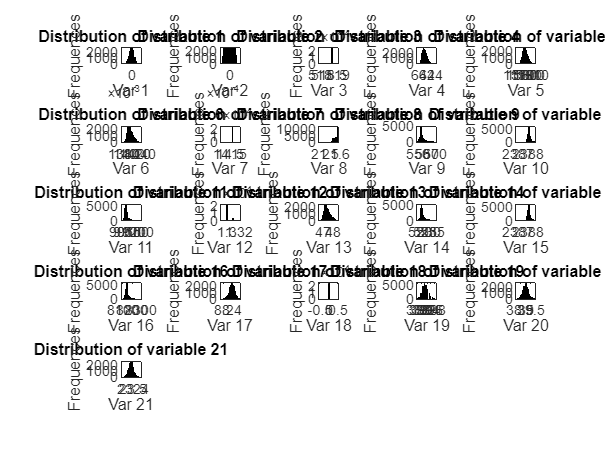

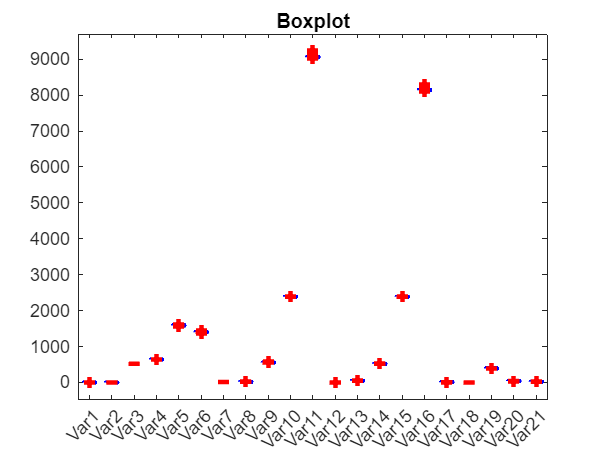

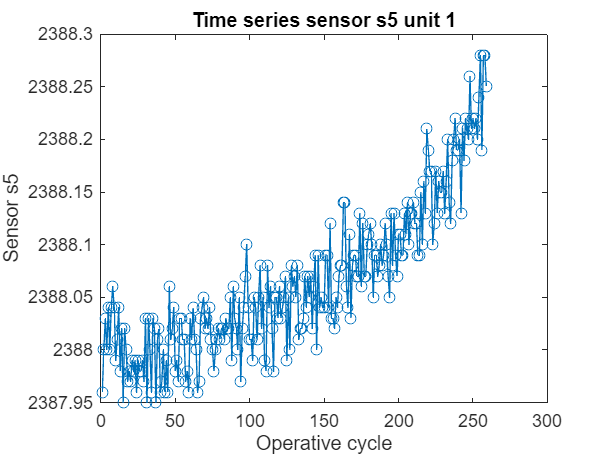

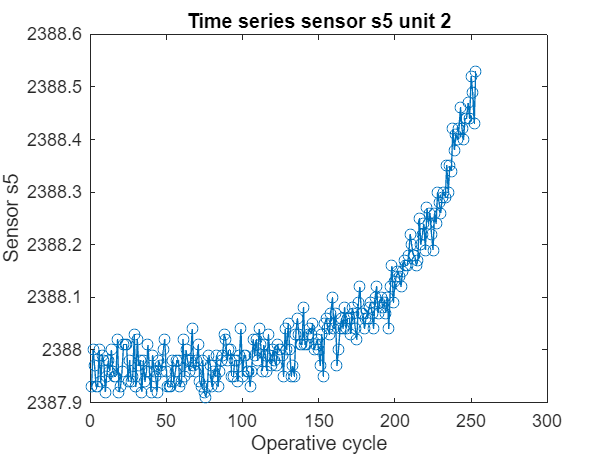

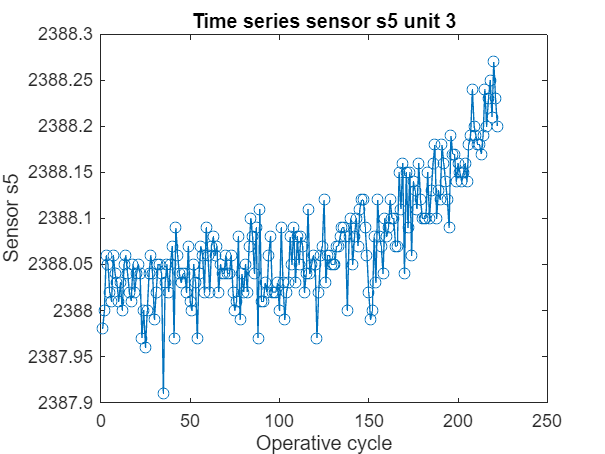


--- PCA Analysis for train_FD003.txt ---


Variance explained by first 10 PCs:


   41.3774   26.3693    5.5818    5.5586    5.1302    4.3408    2.3984    1.8835    1.7029    1.3850



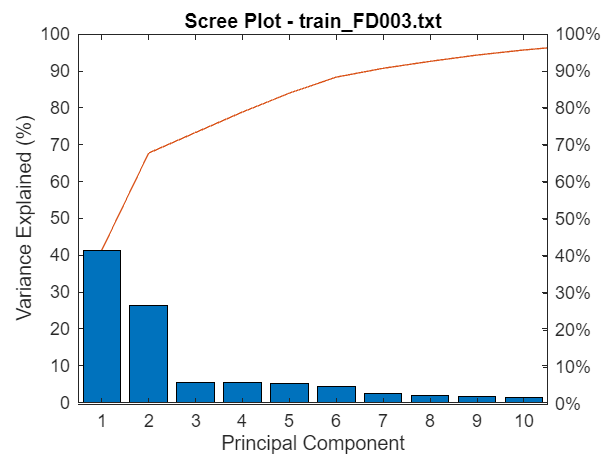

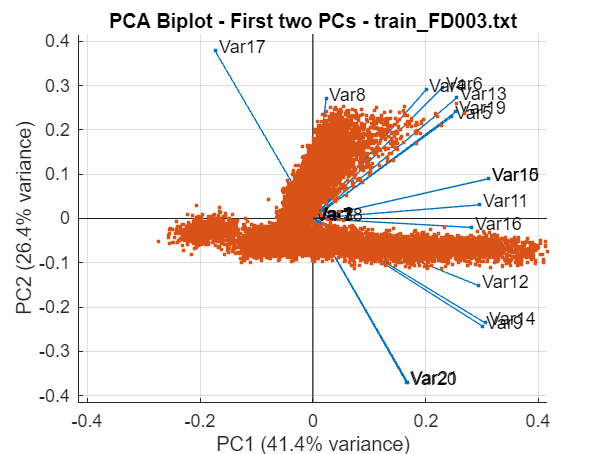

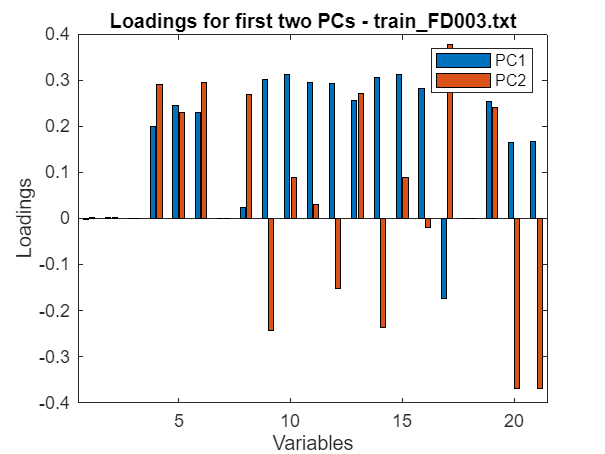


Starting MSPC Modeling for Dataset: train_FD003.txt


No constant variables found.


Dataset has 24720 observations and 21 predictive variables after preprocessing.


 Analysis dataset: train_FD004.txt


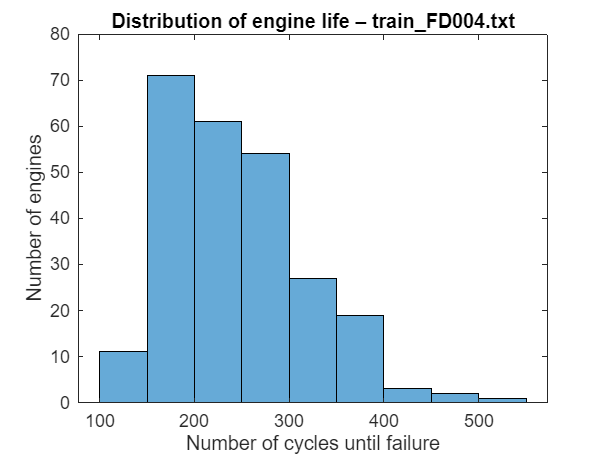

Number of engines: 249


Average engine life (cycles): 245.98


No missing values.


No constant variables.


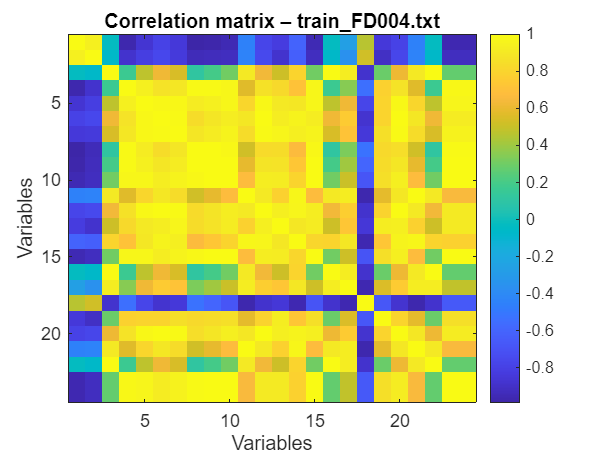

Dataset has 61249 observations (rows) and 24 predictive variables (columns).


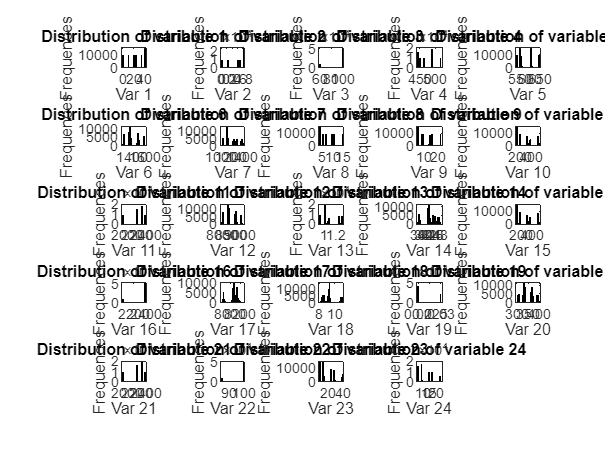

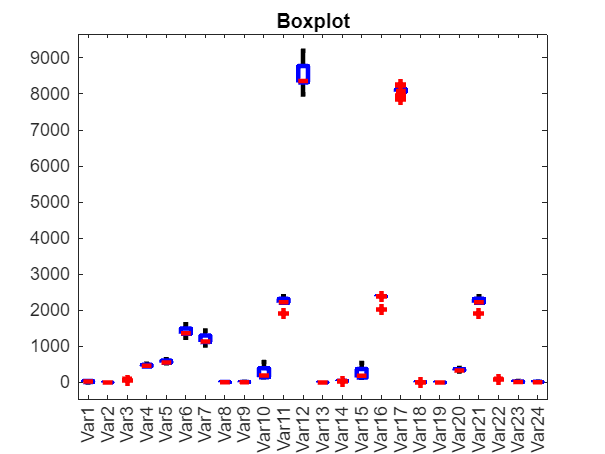

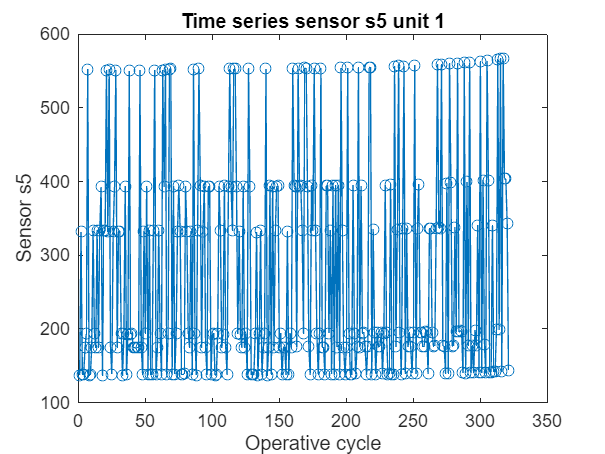

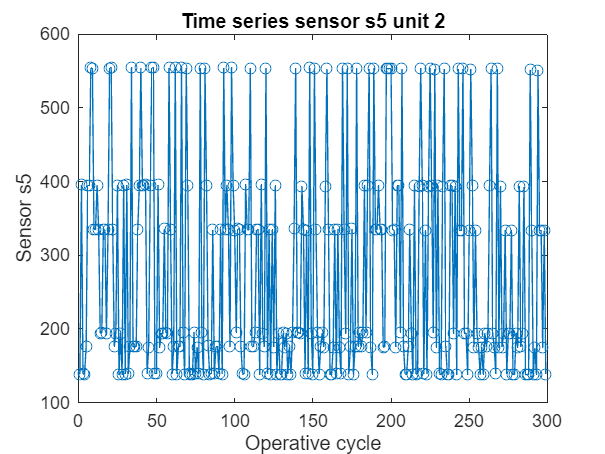

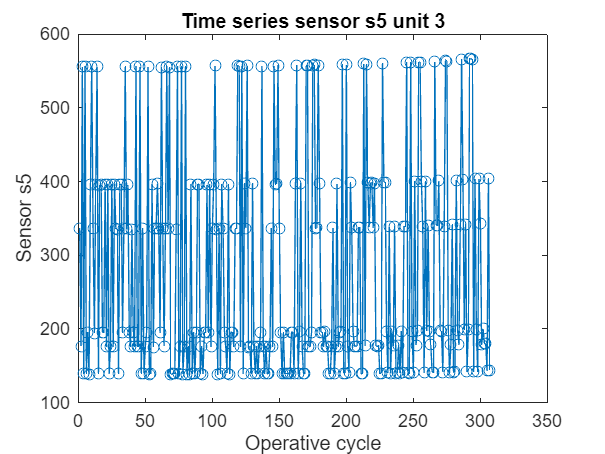


--- PCA Analysis for train_FD004.txt ---


Variance explained by first 10 PCs:


   77.3578   19.9629    1.9862    0.3184    0.1702    0.0788    0.0647    0.0297    0.0133    0.0056



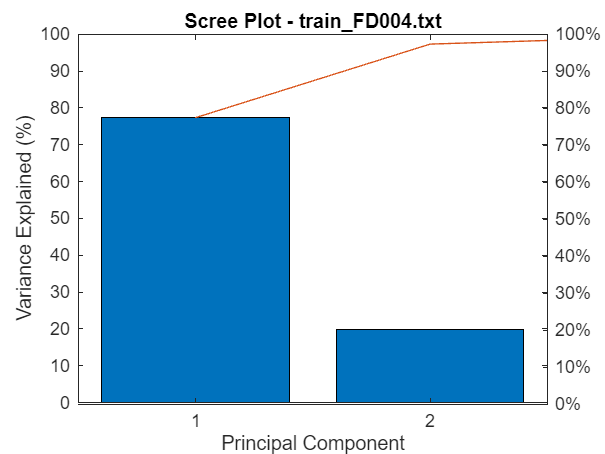

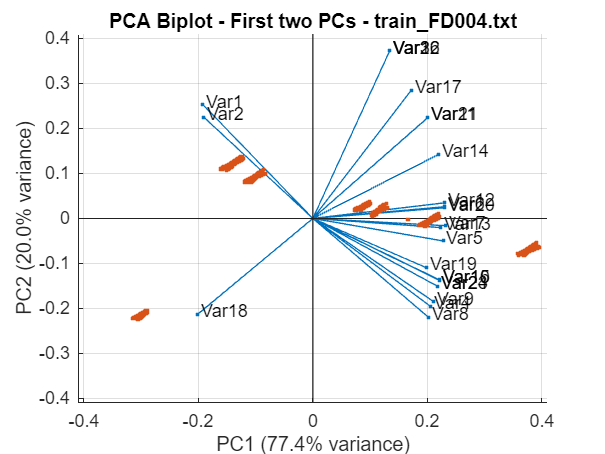

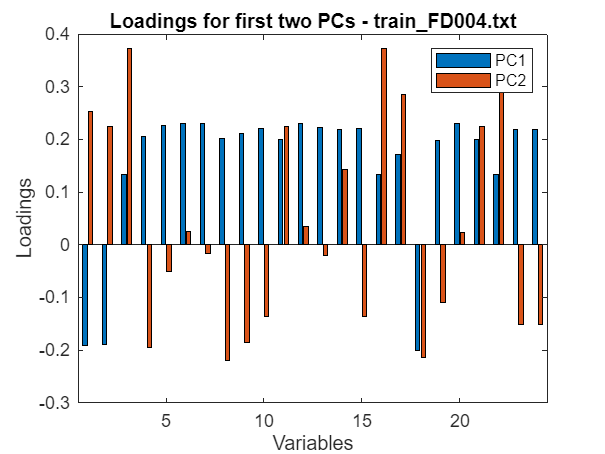


Starting MSPC Modeling for Dataset: train_FD004.txt


No constant variables found.


Dataset has 61249 observations and 24 predictive variables after preprocessing.


trainFiles = {'train_FD001.txt', 'train_FD002.txt', 'train_FD003.txt', 'train_FD004.txt'};

for f = 1:numel(trainFiles)
    fprintf('\n==============================\n');
    fprintf(' Analysis dataset: %s\n', trainFiles{f});
    fprintf('==============================\n');

    trainData = readmatrix(trainFiles{f});

    unit_train = trainData(:,1);
    cycle_train = trainData(:,2);
    X_train = trainData(:,3:end);

    % Check non synchronized time series
    uniqueUnits = unique(unit_train);
    nUnits = numel(uniqueUnits);
    cyclesPerUnit = zeros(nUnits,1);

    for i = 1:nUnits
        cyclesPerUnit(i) = sum(unit_train==uniqueUnits(i));
    end

    % Remaining Useful Life (RUL) calculation for training set
    RUL_train = zeros(size(cycle_train)); 

    for i = 1:nUnits
        idx = (unit_train == uniqueUnits(i));
        maxCycle = max(cycle_train(idx));
        RUL_train(idx) = maxCycle - cycle_train(idx);
    end

    trainData_withRUL = [unit_train cycle_train X_train RUL_train];

    figure;
    histogram(cyclesPerUnit);
    xlabel('Number of cycles until failure');
    ylabel('Number of engines');
    title(sprintf('Distribution of engine life – %s', trainFiles{f}), 'Interpreter','none');

    fprintf('Number of engines: %d\n', nUnits);
    fprintf('Average engine life (cycles): %.2f\n', mean(cyclesPerUnit));

    % Check missing values
    nMissing = sum(isnan(X_train),1);
    missingVars = find(nMissing>0);

    if ~isempty(missingVars)
        fprintf('Variables with missing values:\n');
        disp(missingVars);
    else
        fprintf('No missing values.\n');
    end

    % Constant variables
    varPerCol = var(X_train);
    constVars = find(varPerCol == 0); 

    if ~isempty(constVars)
        fprintf('Constant variables:\n');
        disp(constVars);
        X_train(:,constVars) = [];
    else
        fprintf('No constant variables.\n');
    end

    % Correlation
    corrMatrix = corr(X_train);
    figure;
    imagesc(corrMatrix);
    colorbar;
    title(sprintf('Correlation matrix – %s', trainFiles{f}), 'Interpreter','none');
    xlabel('Variables');
    ylabel('Variables');

    % Number of observation and variables
    [nObs, nVar] = size(X_train);
    fprintf('Dataset has %d observations (rows) and %d predictive variables (columns).\n', nObs, nVar);

    % Histograms
    figure;
    for i = 1:min(24,nVar)
        subplot(5,5,i);
        histogram(X_train(:,i),30,'FaceColor',[0.2 0.6 0.8],'EdgeColor','k');
        xlabel(sprintf('Var %d', i));
        ylabel('Frequences');
        title(sprintf('Distribution of variable %d', i));
    end

    % Boxplot for outliers
    figure;
    boxplot(X_train(:,1:min(24,nVar)),'Labels',arrayfun(@(x) sprintf('Var%d',x),1:min(24,nVar),'UniformOutput',false));
    title('Boxplot');
    h = findobj(gca,'Type','line');
    set(h,'LineWidth',2.5);

    % Visualize time series of engine
    for unitID = 1:3
        idx = (unit_train == unitID);
        figure;
        plot(cycle_train(idx), X_train(idx,10), '-o'); % for example sensor 5
        xlabel('Operative cycle');
        ylabel('Sensor s5');
        title(sprintf('Time series sensor s5 unit %d', unitID));
    end

    % PCA Exploratory Data Analysis
    fprintf('\n--- PCA Analysis for %s ---\n', trainFiles{f});

    % Normalize the data to zero mean and unit variance before PCA
    X_norm = zscore(X_train);

    % Perform PCA
    [coeff, score, latent, tsquared, explained, mu] = pca(X_norm);

    % Display variance explained by first 10 PCs
    fprintf('Variance explained by first 10 PCs:\n');
    disp(explained(1:min(10,length(explained)))');

    % Scree plot - variance explained
    figure;
    pareto(explained);
    xlabel('Principal Component');
    ylabel('Variance Explained (%)');
    title(sprintf('Scree Plot - %s', trainFiles{f}), 'Interpreter','none');

    % Biplot of first two principal components
    figure;
    biplot(coeff(:,1:2), 'Scores', score(:,1:2), ...
        'VarLabels', arrayfun(@(x) sprintf('Var%d', x), 1:nVar, 'UniformOutput', false));
    xlabel(sprintf('PC1 (%.1f%% variance)', explained(1)));
    ylabel(sprintf('PC2 (%.1f%% variance)', explained(2)));
    title(sprintf('PCA Biplot - First two PCs - %s', trainFiles{f}), 'Interpreter','none');

    % Loading plot for first two principal components
    figure;
    bar(coeff(:,1:2));
    xlabel('Variables');
    ylabel('Loadings');
    legend({'PC1','PC2'});
    title(sprintf('Loadings for first two PCs - %s', trainFiles{f}), 'Interpreter','none');

    % MSPC Modeling for current dataset
    fprintf('\nStarting MSPC Modeling for Dataset: %s\n', trainFiles{f});
    fprintf('========================================\n');

    % Load Test and RUL Data for the Current Dataset 
    testFile = strrep(trainFiles{f}, 'train', 'test');
    rulFile = strrep(trainFiles{f}, 'train', 'RUL');
    testData = readmatrix(testFile);
    RUL_true = readmatrix(rulFile);

    % Preprocessing: Remove constant variables
    varPerCol = var(X_train);
    constVars = find(varPerCol == 0); 
    if ~isempty(constVars)
        fprintf('Found and removed %d constant variables.\n', numel(constVars));
        X_train(:,constVars) = [];
    else
        fprintf('No constant variables found.\n');
    end

    [nObs, nVar] = size(X_train);
    fprintf('Dataset has %d observations and %d predictive variables after preprocessing.\n', nObs, nVar);

end